# Šesta naloga

load('ts_model.mat');


## Referenčni model za sledenje

s = tf("s");
Gr = 5/(s + 5);
sys_r = c2d(ss(Gr), 0.01, 'zoh');
Ar = sys_r.A;
Br = sys_r.B;
Cr = sys_r.C;


## definiranje referenčnega signala

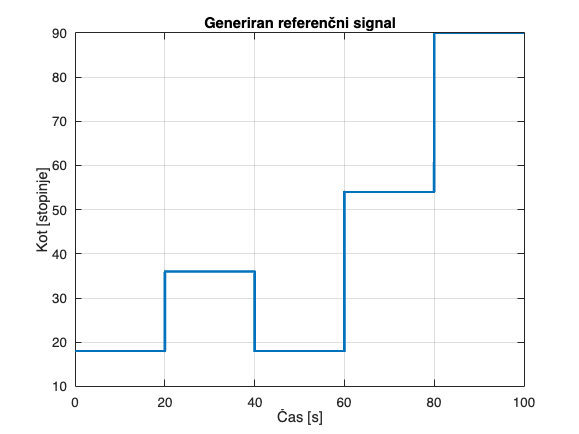

t = 0:0.01:99.99;
N = length(t);
w = ones(1, N);
w(1:2000) = w(1:2000)*18;
w(2001:4000) = w(2001:4000)*36;
w(4001:6000) = w(4001:6000)*18;
w(6001:8000) = w(6001:8000)*54;
w(8001:end) = w(8001:end)*90;


% Prikaz referenčnega signala
figure;
plot(t, w, 'LineWidth', 2);
title('Generiran referenčni signal');
xlabel('Čas [s]');
ylabel('Kot [stopinje]');
grid on;

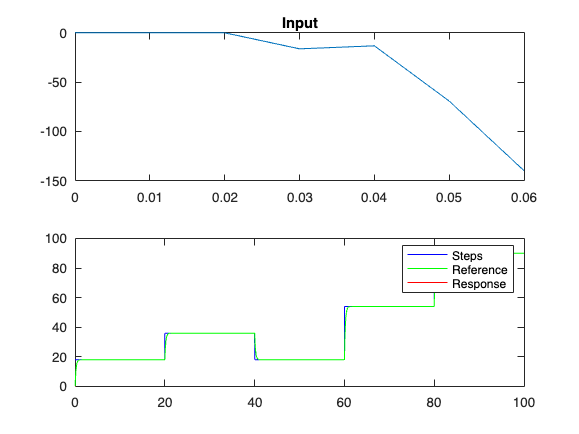

% Inicializacija potrebnih spremenljivk
H = 3; % Prediktivni horizont
t = 0:0.01:99.99;
N = length(t);
y = zeros(N, 1);
u = zeros(N+1, 1);
xm = [0; 0]; % Inicializacija stanja modela
xr = 0; % Inicializacija stanja referenčnega sistema
xp = [0, 0]; % Inicializacija stanja sistema (helio-crane)

% Glavna zanka
for i = 3:N
    % Priprava vhodnega vektorja za pretvorbo v prostor stanj
    % Vektor x mora vsebovati pretekle vrednosti izhodov in vhodov
    x = [-y(i-1); -y(i-2); u(i-1); u(i-2)];
    
    % Klic funkcije za pretvorbo TS modela v state-space model
    [Am, Bm, Cm, Rm] = TS_to_SS(C, O, W, b, x);
    
    % Nadaljevanje s simulacijo in regulacijo...
    % Napovedovanje izhoda referenčnega sistema
    yr(i) = Cr * xr;
    ym(i) = Cm * xm;

    % Simulacija sistema helio-crane (posodobi stanja)
    [xp(2), xp(1)] = helicrane(u(i), xp); % Funkcija helicrane simulira fizični sistem
    y(i) = xp(2); % Trenutni izhod sistema

    % Izračun prediktivnega regulatorja
    G0 = Cm * (Am^H - eye(2)) * pinv(Am - eye(2)) * Bm;
    G = pinv(G0) * (1 - Ar^H);
    
    % Posodobitev kontrolnega signala
    u(i+1) = G * (w(i) - y(i)) + pinv(G0) * ym(i) - pinv(G0) * Cm * Am^H * xm - pinv(Bm) * Rm;

    % Posodobitev stanj
    xr = Ar * xr + Br * w(i);
    xm = Am * xm + Bm * u(i+1) + Rm;
end

figure;
subplot(2, 1, 1);
plot(t, u(1:end-1));
title("Input");

subplot(2, 1, 2);
title("Response");
plot(t, w, "blue");
hold on;
plot(t, yr, "green");
plot(t, y, "red");
legend("Steps", "Reference", "Response");

function [Am, Bm, Cm, Rm] = TS_to_SS(C, O, W, b, x)
    % Predpostavka: x = [-y(k-1); -y(k-2); u(k-1); u(k-2)]
    R = size(C, 1);
    Am = zeros(2, 2);
    Bm = zeros(2, 1);
    Rm = zeros(2, 1);
    Cm = [0 1];
    
    % Izračun pripadnostnih funkcij
    mu = exp(-0.5 * sum((x' - C).^2 ./ (O.^2), 2));
    mu = mu / sum(mu); % Normalizacija
    
    % Izračun sistemskih matrik na podlagi pripadnostnih funkcij
    for i = 1:R
        Am = Am + mu(i) * [0, -W(i, 4); 1, -W(i, 3)];
        Bm = Bm + mu(i) * [W(i, 2); W(i, 1)];
        Rm = Rm + mu(i) * [0; b(i)];
    end
end
